clc; clear all; close all;
rng(0)

Creating a neural network  for openfast based on full state estimation, it would be ideal to extend this model to include full-state estimation based only on commonly available measurements of the commercial turbine. These measurments are also available in real time; these SCADA measurments are:

1.) Tower-top acceleration

2.) Pitch angle

3.) Generator torque

4.) Rotational speed of turbine shaft

We could try to construct a traditional NN to estimate the full-state of the turbine based on the available real time data. If we do this, we could estimate things such as produced power, or loads in the tower/platform connection, and incorporate these states in the reward function. I.e high reward for energy, and a negative reward for high loads.

I'd like to keep this problem realistic, because I see potential real world application if the controller for the wind turbine only needs a "software update", that is, replacing a standard control theory controller with a Deep Reinforcement Learning NN. In the future, this means I will construct the model with the assumption I can only measure SCADA measurements, and increase complexity with a **DeepFAST** block to estimate full states based on SCADA measurements. We might need to introduce another measurment if we fail to find any significant correalation.

First we must define the observation information. In the current OpenFAST simulation, the default settings are for 99 outputs, so for simplicity, I will just use all of them (minus time).

nObsStates = 4;
obsInfo = rlNumericSpec([nObsStates 1]) ;
Neurons = 256 ;

MaxMoment = 100000 ;
Cpitch = 1 ;
Cmoment = 2.5 ;
Penalty = 5000 ;

Then define the available actuation actions, in this case, I will just be using the cable control, so changing the length of the mooring system by the fairlead, we can influence the dynamics of the system inside OpenFAST via the Simulink block. This could be further increased to blade pitch control, generator speed, and others, creating a more complex system with communication between turbine blades and mooring control.

nActStates = 3 ; % 3 Mooring Lines (3 change in lengths)
actInfo = rlNumericSpec([nActStates 1],"UpperLimit",1,"LowerLimit",-1);

We are also allowed to specify an upper and lower limit of the actuation, dimensions depend solely on the input, therefore, we are limited to changing the cable length between -1 and 1, but we scale it up with a gain filter in the Simulink diagram so the mooring lines are constrained between -6m and 6m.

Now we must create the environment from Simulink simulation using the OpenFAST S-Func block. The FAST S-Func allows us to force the turbine during the simulation, and recovering information about the states as that simulation is on going. An additional block is needed in the Simulink model to tell MATLAB "we would like to apply the reinforcement learning here", connecting the observed states, to the recommended actuations. This is the "controller" block.

env = rlSimulinkEnv("DeepRL_FASTnew2", "DeepRL_FASTnew2/controller",obsInfo,actInfo) ;
env.UseFastRestart = 'off' ;
Ts = 0.1;          % Sample time for RL controller, not necessarily OF time step
LearnRate = 0.005 ; % Steepness at which it will perform the gradient descent
%env.ResetFcn = @randomstart ;

We have to tell MATLAB information about the model such as the available observation info, and available actions to take in the environment

We then can create a neural network for the actions, followed by creating a neural network for the observation. These two neural networks are used to critique and update the models policy to maximize the reward.

actnet = [featureInputLayer(nObsStates,"Name","obs"),fullyConnectedLayer(Neurons,"Name",'fc1'),reluLayer("Name",'relu1'),fullyConnectedLayer(Neurons,"Name",'fc2'),reluLayer("Name",'relu2'),fullyConnectedLayer(Neurons,"Name",'fc3'),reluLayer("Name",'relu3'),fullyConnectedLayer(nActStates,"Name","act"),tanhLayer("Name","tanh"),scalingLayer("Name","scact",Scale=max(actInfo.UpperLimit))]

actnet =   1×10 Layer array with layers:

     1   'obs'     Feature Input     4 features
     2   'fc1'     Fully Connected   256 fully connected layer
     3   'relu1'   ReLU              ReLU
     4   'fc2'     Fully Connected   256 fully connected layer
     5   'relu2'   ReLU              ReLU
     6   'fc3'     Fully Connected   256 fully connected layer
     7   'relu3'   ReLU              ReLU
     8   'act'     Fully Connected   3 fully connected layer
     9   'tanh'    Tanh              Hyperbolic tangent
    10   'scact'   ScalingLayer      Scaling layer

We can use this NN to create an actor for the model, or how the NN interacts with the environment (OpenFAST)

actorOpts = rlOptimizerOptions('LearnRate',LearnRate);
actor = rlDeterministicActorRepresentation(actnet,obsInfo,actInfo,"Observation",'obs','Action','scact')

actor =   rlDeterministicActorRepresentation with properties:

         ActionInfo: [1×1 rl.util.rlNumericSpec]
    ObservationInfo: [1×1 rl.util.rlNumericSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


Create Q-Value critic for use in DDPG

obsPath = [featureInputLayer(nObsStates,"Name","obs"),fullyConnectedLayer(Neurons,"Name",'fc1'),reluLayer("Name",'relu1'),fullyConnectedLayer(Neurons,"Name",'fc2'),additionLayer(nActStates,"Name","add"),reluLayer("Name",'relu2'),fullyConnectedLayer(Neurons,"Name",'fc3'),reluLayer("Name",'relu3'),fullyConnectedLayer(1,"Name","value")];
actPath = [featureInputLayer(nActStates,"Normalization","none","Name","act")
    fullyConnectedLayer(Neurons,"Name","fcact")]

actPath =   2×1 Layer array with layers:

     1   'act'     Feature Input     3 features
     2   'fcact'   Fully Connected   256 fully connected layer

From the graph, we can see that while the state approaches -5, a positive reward is gained. It is up to the NN to determine the best way to maximize this reward by learning how its action increases the reward. We must now create the critic network, this is essentially just joining the neural nets we created in the correct way.

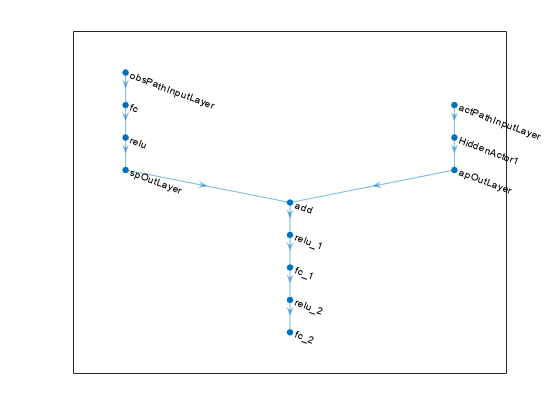

% qvalnet = layerGraph(obsPath) ;
% qvalnet = addLayers(qvalnet,actPath) ;
% for i = 2:nActStates
%     a = num2str(i) ;
%     b = 'add/in' ;
%     c = [b a] ;
%     qvalnet = connectLayers(qvalnet,'fcact',c )
% end
% plot(qvalnet)
statePath = [
    featureInputLayer( ...
        obsInfo.Dimension(1), ...
        Name="obsPathInputLayer")
    fullyConnectedLayer(Neurons)
    reluLayer
    fullyConnectedLayer(Neurons,Name="spOutLayer")
    ];

% Define action path
actionPath = [
    featureInputLayer( ...
        actInfo.Dimension(1), ...
        Name="actPathInputLayer")
    fullyConnectedLayer(Neurons, ...
        Name="HiddenActor1", ...
        BiasLearnRateFactor=0)
    fullyConnectedLayer(Neurons, ...
        Name="apOutLayer", ...
        BiasLearnRateFactor=0)
    ];

% Define common path
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(Neurons)
    reluLayer
    fullyConnectedLayer(1)
    ];

% Create layergraph, add layers and connect them
criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"spOutLayer","add/in1");
criticNetwork = connectLayers(criticNetwork,"apOutLayer","add/in2");
plot(criticNetwork)

Create the critic object based on the Q-value critic we just created and connected

% criticOpts = rlOptimizerOptions('LearnRate',LearnRate);
% critic = rlQValueRepresentation(qvalnet,obsInfo,actInfo,"Observation","obs","Action","act");
critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsPathInputLayer", ...
    ActionInputNames="actPathInputLayer");
criticOpts = rlOptimizerOptions(LearnRate=LearnRate,GradientThreshold=1);
actorOpts = rlOptimizerOptions(LearnRate=LearnRate,GradientThreshold=1);

Now we must create the agent, or the combined actor/critic of the model. This is responsible for interacting with the environment, and obtaining data about what it has done.

agentOpts = rlDDPGAgentOptions(...
                'ActorOptimizerOptions',actorOpts,...
                'CriticOptimizerOptions',criticOpts,...
                'SampleTime',Ts,...
                'MiniBatchSize',128,...
                'NumStepsToLookAhead',50,...
                'DiscountFactor',0.99);
agent = rlDDPGAgent(actor,critic,agentOpts) ;

Lets set some OpenFAST settings. TMax has to be large or else the S-Func OpenFAST block will end when this time is reached.

FAST_InputFileName = '5MW_OC4Semi_WSt_WavesWN.fst';
TMax               = 500; % seconds

Not much, lets begin training:

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',5000,...
    'MaxStepsPerEpisode',600,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',200000,...
    'ScoreAveragingWindowLength',5,...
    'SaveAgentCriteria',"EpisodeReward",...
    'SaveAgentValue',5000,Plots="training-progress");

info = train(agent,env,trainOpts) ;

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:30:34-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or improperly formatted.
 Ru

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.493, Vy = -4.0504, rlocal = 11.723, theta = 1.0732, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:30:53-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.025, Vy = -4.0193, rlocal = 11.721, theta = 1.2153, geometric phi = 1.6561. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.39, Vy = -4.0243, rlocal = 11.721, theta = 1.219, geometric phi = 1.6555. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.405, Vy = -3.5001, rlocal = 11.719, theta = 1.3453, geometric phi = 1.6445. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.277, Vy = -3.5582, rlocal = 11.72, theta = 1.2743, geometric phi = 1.6459. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.422, Vy = -3.86, rlocal = 11.72, theta = 1.2503, geometric phi = 1.652. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.114, Vy = -3.4981, rlocal = 11.72, theta = 1.2841, geometric phi = 1.6449. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:31:28-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:31:32-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.489, Vy = -4.0519, rlocal = 11.722, theta = 1.1467, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:31:42-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:31:47-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.48, Vy = -4.1503, rlocal = 11.726, theta = 0.90911, geometric phi = 1.658. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:31:56-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.438, Vy = -3.6789, rlocal = 11.72, theta = 1.2985, geometric phi = 1.6482. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.433, Vy = -3.5234, rlocal = 11.719, theta = 1.3359, geometric phi = 1.6449. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.796, Vy = -4.1609, rlocal = 11.721, theta = 1.1728, geometric phi = 1.6595. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.394, Vy = -3.9147, rlocal = 11.72, theta = 1.2597, geometric phi = 1.6532. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.416, Vy = -3.5914, rlocal = 11.719, theta = 1.3163, geometric phi = 1.6464. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:32:27-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:32:32-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 1):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 42.858, Vy = -3.7233, rlocal = 11.726, theta = 0.91991, geometric phi = 1.6575. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:32:45-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:32:50-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:32:55-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:00-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 1):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 42.787, Vy = -3.3349, rlocal = 11.72, theta = 1.2755, geometric phi = 1.6486. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:16-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:21-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:26-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:31-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.445, Vy = -3.7588, rlocal = 11.72, theta = 1.2529, geometric phi = 1.6499. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:41-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:46-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:51-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:33:59-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:04-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:09-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:14-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:19-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:24-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:29-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:34-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:40-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:45-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 1):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 42.704, Vy = -3.3247, rlocal = 11.719, theta = 1.3128, geometric phi = 1.6485. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:34:57-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.507, Vy = -4.0465, rlocal = 11.728, theta = 0.84441, geometric phi = 1.6558. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:35:07-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:35:12-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.49, Vy = -4.1118, rlocal = 11.725, theta = 0.94032, geometric phi = 1.6572. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:35:23-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.907, Vy = -3.7371, rlocal = 11.732, theta = 0.67677, geometric phi = 1.6503. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.456, Vy = -3.6165, rlocal = 11.72, theta = 1.3001, geometric phi = 1.6469. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.898, Vy = -3.4931, rlocal = 11.719, theta = 1.3148, geometric phi = 1.6451. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:35:43-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.888, Vy = -4.27, rlocal = 11.726, theta = 0.90452, geometric phi = 1.6616. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.495, Vy = -4.108, rlocal = 11.728, theta = 0.84147, geometric phi = 1.6571. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:35:58-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.447, Vy = -3.8338, rlocal = 11.73, theta = 0.72767, geometric phi = 1.6514. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.052, Vy = -4.1728, rlocal = 11.723, theta = 1.0418, geometric phi = 1.6592. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 1):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 42.966, Vy = -3.5745, rlocal = 11.729, theta = 0.76449, geometric phi = 1.6538. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:36:24-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:36:29-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 1):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 42.654, Vy = -3.2306, rlocal = 11.732, theta = 0.65305, geometric phi = 1.6464. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:36:42-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:36:47-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:36:51-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:36:56-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:01-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:07-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:12-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:17-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:22-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:27-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:32-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:37-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:42-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:47-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:52-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:37:58-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:03-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:08-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:13-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:18-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:26-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:31-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:36-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:43-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:48-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:38:56-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:01-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:06-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:11-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:16-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:21-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:27-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:32-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:37-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:42-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:47-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:52-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:39:57-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:02-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:07-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:12-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:17-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:22-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:27-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:32-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:38-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:44-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:40:52-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.815, Vy = -4.0696, rlocal = 11.722, theta = 1.1277, geometric phi = 1.6575. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:02-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:07-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.958, Vy = -3.9065, rlocal = 11.73, theta = 0.73485, geometric phi = 1.6538. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.447, Vy = -3.9217, rlocal = 11.73, theta = 0.75434, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:25-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:30-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:35-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.852, Vy = -4.0986, rlocal = 11.721, theta = 1.1982, geometric phi = 1.6581. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:46-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:51-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:41:56-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:01-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:06-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:11-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:16-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:21-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:26-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:31-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:37-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.958, Vy = -3.9865, rlocal = 11.722, theta = 1.1306, geometric phi = 1.6555. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:47-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:52-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:42:57-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:43:02-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.48, Vy = -3.95, rlocal = 11.73, theta = 0.73355, geometric phi = 1.6538. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.941, Vy = -4.1977, rlocal = 11.726, theta = 0.89807, geometric phi = 1.66. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.231, Vy = -3.8773, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.388, Vy = -3.9346, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.212, Vy = -3.9066, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.967, Vy = -3.9602, rlocal = 11.722, theta = 1.093, geometric phi = 1.6549. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.076, Vy = -3.8981, rlocal = 11.721, theta = 1.1791, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.306, Vy = -3.5319, rlocal = 11.719, theta = 1.3385, geometric phi = 1.6453. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.489, Vy = -4.0519, rlocal = 11.722, theta = 1.147, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.366, Vy = -3.7214, rlocal = 11.719, theta = 1.31, geometric phi = 1.6492. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.485, Vy = -4.0536, rlocal = 11.72, theta = 1.228, geometric phi = 1.656. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.481, Vy = -4.1174, rlocal = 11.721, theta = 1.1984, geometric phi = 1.6573. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.291, Vy = -3.904, rlocal = 11.728, theta = 0.81543, geometric phi = 1.6532. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.493, Vy = -4.1093, rlocal = 11.727, theta = 0.87381, geometric phi = 1.6571. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.378, Vy = -3.8964, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.369, Vy = -3.8997, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.175, Vy = -3.9142, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.272, Vy = -3.8786, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.199, Vy = -3.8894, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.27, Vy = -3.8784, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.228, Vy = -3.903, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6532. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.275, Vy = -4.0105, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6554. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.23, Vy = -3.9073, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.283, Vy = -3.878, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.255, Vy = -3.8865, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.246, Vy = -3.9318, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6538. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.124, Vy = -4.0715, rlocal = 11.725, theta = 0.96061, geometric phi = 1.657. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.497, Vy = -4.0978, rlocal = 11.727, theta = 0.85292, geometric phi = 1.6569. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.029, Vy = -4.0134, rlocal = 11.722, theta = 1.1087, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.041, Vy = -4.1917, rlocal = 11.724, theta = 1.0273, geometric phi = 1.6597. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.485, Vy = -4.0538, rlocal = 11.72, theta = 1.235, geometric phi = 1.656. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.145, Vy = -3.731, rlocal = 11.72, theta = 1.2288, geometric phi = 1.6498. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.081, Vy = -3.7912, rlocal = 11.72, theta = 1.2446, geometric phi = 1.6511. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.472, Vy = -4.1143, rlocal = 11.722, theta = 1.1306, geometric phi = 1.6572. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.237, Vy = -3.9745, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6547. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.433, Vy = -3.89, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.216, Vy = -3.8846, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.482, Vy = -4.1173, rlocal = 11.721, theta = 1.1794, geometric phi = 1.6573. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.319, Vy = -3.8416, rlocal = 11.721, theta = 1.1908, geometric phi = 1.6518. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.033, Vy = -4.0528, rlocal = 11.726, theta = 0.92178, geometric phi = 1.6568. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.06, Vy = -3.8086, rlocal = 11.721, theta = 1.2031, geometric phi = 1.6516. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.407, Vy = -3.9855, rlocal = 11.72, theta = 1.2395, geometric phi = 1.6547. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.202, Vy = -4.1191, rlocal = 11.726, theta = 0.90036, geometric phi = 1.6578. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.288, Vy = -3.5943, rlocal = 11.719, theta = 1.3291, geometric phi = 1.6467. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.116, Vy = -4.0468, rlocal = 11.725, theta = 0.98523, geometric phi = 1.6565. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.007, Vy = -4.167, rlocal = 11.721, theta = 1.1548, geometric phi = 1.6592. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.327, Vy = -3.7199, rlocal = 11.72, theta = 1.2968, geometric phi = 1.6492. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.277, Vy = -3.4825, rlocal = 11.72, theta = 1.2994, geometric phi = 1.6443. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.447, Vy = -3.8501, rlocal = 11.72, theta = 1.2418, geometric phi = 1.6518. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.073, Vy = -4.0377, rlocal = 11.722, theta = 1.1427, geometric phi = 1.6564. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.165, Vy = -4.1154, rlocal = 11.725, theta = 0.96615, geometric phi = 1.6578. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.183, Vy = -4.2242, rlocal = 11.723, theta = 1.0413, geometric phi = 1.6601. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.342, Vy = -3.8921, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.43, Vy = -3.8939, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.433, Vy = -3.9401, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.199, Vy = -3.9248, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6538. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.253, Vy = -3.8807, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.21, Vy = -3.9037, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.266, Vy = -4.0389, rlocal = 11.729, theta = 0.80327, geometric phi = 1.656. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.243, Vy = -4.0856, rlocal = 11.725, theta = 0.93813, geometric phi = 1.6571. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.365, Vy = -3.9515, rlocal = 11.729, theta = 0.80327, geometric phi = 1.654. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.224, Vy = -4.0856, rlocal = 11.728, theta = 0.8329, geometric phi = 1.6571. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.272, Vy = -3.8785, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.43, Vy = -3.9364, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.554, Vy = -3.9524, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.492, Vy = -4.0508, rlocal = 11.722, theta = 1.0945, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.028, Vy = -4.1418, rlocal = 11.722, theta = 1.1476, geometric phi = 1.6586. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.228, Vy = -3.9806, rlocal = 11.727, theta = 0.85523, geometric phi = 1.6549. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.276, Vy = -3.8925, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.286, Vy = -3.6819, rlocal = 11.72, theta = 1.3026, geometric phi = 1.6485. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.241, Vy = -3.8805, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.288, Vy = -3.8814, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.388, Vy = -3.9065, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.48, Vy = -3.9582, rlocal = 11.729, theta = 0.80327, geometric phi = 1.654. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.585, Vy = -3.9936, rlocal = 11.728, theta = 0.80883, geometric phi = 1.6545. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.493, Vy = -4.0504, rlocal = 11.723, theta = 1.0712, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.5, Vy = -4.0546, rlocal = 11.73, theta = 0.7568, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.87, Vy = -3.5224, rlocal = 11.72, theta = 1.2652, geometric phi = 1.6458. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.289, Vy = -4.122, rlocal = 11.727, theta = 0.8765, geometric phi = 1.6577. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.348, Vy = -3.9523, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6541. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.368, Vy = -3.9335, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.184, Vy = -3.8767, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.272, Vy = -3.9144, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.267, Vy = -4.0841, rlocal = 11.727, theta = 0.8806, geometric phi = 1.657. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.426, Vy = -4.0273, rlocal = 11.721, theta = 1.1922, geometric phi = 1.6555. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:52:27-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.428, Vy = -4.0497, rlocal = 11.721, theta = 1.176, geometric phi = 1.656. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 07:52:37-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.239, Vy = -3.3666, rlocal = 11.719, theta = 1.349, geometric phi = 1.6419. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.932, Vy = -4.0733, rlocal = 11.723, theta = 1.0375, geometric phi = 1.6574. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.237, Vy = -3.9937, rlocal = 11.72, theta = 1.2338, geometric phi = 1.6551. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.464, Vy = -3.5817, rlocal = 11.731, theta = 0.69974, geometric phi = 1.6461. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.29, Vy = -3.4102, rlocal = 11.733, theta = 0.62491, geometric phi = 1.6428. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.341, Vy = -3.9016, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.301, Vy = -3.8859, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.274, Vy = -3.8808, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.301, Vy = -3.8858, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.295, Vy = -3.881, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.305, Vy = -3.8831, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.302, Vy = -3.8847, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.275, Vy = -3.8849, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.289, Vy = -3.8844, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.36, Vy = -3.885, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.495, Vy = -3.9699, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6542. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.275, Vy = -3.896, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.301, Vy = -3.8857, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.212, Vy = -3.8912, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.276, Vy = -3.9845, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6549. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.547, Vy = -3.9817, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6543. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.435, Vy = -3.9212, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.791, Vy = -3.5196, rlocal = 11.72, theta = 1.2811, geometric phi = 1.6459. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.281, Vy = -3.4265, rlocal = 11.719, theta = 1.3594, geometric phi = 1.6431. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.05, Vy = -4.0216, rlocal = 11.722, theta = 1.1495, geometric phi = 1.6561. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.17, Vy = -4.0572, rlocal = 11.724, theta = 1.0216, geometric phi = 1.6566. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.277, Vy = -3.8906, rlocal = 11.721, theta = 1.1687, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.353, Vy = -3.7534, rlocal = 11.72, theta = 1.2534, geometric phi = 1.6499. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.287, Vy = -3.7823, rlocal = 11.721, theta = 1.2126, geometric phi = 1.6506. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.392, Vy = -3.9224, rlocal = 11.72, theta = 1.2624, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.486, Vy = -4.1149, rlocal = 11.723, theta = 1.0424, geometric phi = 1.6572. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.138, Vy = -4.0713, rlocal = 11.726, theta = 0.93531, geometric phi = 1.657. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.258, Vy = -3.7277, rlocal = 11.72, theta = 1.2995, geometric phi = 1.6495. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.165, Vy = -3.6698, rlocal = 11.72, theta = 1.2403, geometric phi = 1.6484. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.303, Vy = -3.8106, rlocal = 11.72, theta = 1.2848, geometric phi = 1.6512. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.015, Vy = -4.169, rlocal = 11.722, theta = 1.121, geometric phi = 1.6592. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.489, Vy = -4.0518, rlocal = 11.722, theta = 1.1413, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.129, Vy = -4.0759, rlocal = 11.721, theta = 1.2021, geometric phi = 1.6571. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.186, Vy = -3.6742, rlocal = 11.72, theta = 1.2412, geometric phi = 1.6485. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 1):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 43.671, Vy = -3.8144, rlocal = 11.723, theta = 1.0813, geometric phi = 1.6579. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.393, Vy = -3.6577, rlocal = 11.72, theta = 1.281, geometric phi = 1.6478. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.524, Vy = -3.9376, rlocal = 11.729, theta = 0.78794, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.365, Vy = -3.5625, rlocal = 11.719, theta = 1.3138, geometric phi = 1.6459. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.303, Vy = -4.1304, rlocal = 11.722, theta = 1.1199, geometric phi = 1.6579. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.295, Vy = -3.8774, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.273, Vy = -3.9782, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6548. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.247, Vy = -3.9053, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.434, Vy = -3.9358, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.434, Vy = -3.8892, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.273, Vy = -3.8771, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.437, Vy = -3.8948, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.29, Vy = -3.9271, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.292, Vy = -3.9033, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6531. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.223, Vy = -3.9035, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.21, Vy = -3.8697, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.037, Vy = -3.838, rlocal = 11.73, theta = 0.74958, geometric phi = 1.6522. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.429, Vy = -3.8662, rlocal = 11.721, theta = 1.186, geometric phi = 1.6521. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.421, Vy = -3.4041, rlocal = 11.733, theta = 0.62083, geometric phi = 1.6425. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.913, Vy = -3.5354, rlocal = 11.72, theta = 1.2675, geometric phi = 1.646. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.945, Vy = -3.2981, rlocal = 11.719, theta = 1.3204, geometric phi = 1.6409. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.172, Vy = -4.1168, rlocal = 11.725, theta = 0.96218, geometric phi = 1.6578. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.301, Vy = -3.8855, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.283, Vy = -3.9073, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6532. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.294, Vy = -3.9262, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.329, Vy = -3.9127, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.336, Vy = -3.9055, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6531. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.235, Vy = -3.8802, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.25, Vy = -3.8733, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.383, Vy = -3.9097, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6531. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.509, Vy = -3.9682, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6541. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.358, Vy = -3.9021, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.482, Vy = -4.1397, rlocal = 11.722, theta = 1.135, geometric phi = 1.6578. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.382, Vy = -3.6584, rlocal = 11.72, theta = 1.3073, geometric phi = 1.6479. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.394, Vy = -4.2556, rlocal = 11.727, theta = 0.86011, geometric phi = 1.6603. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.514, Vy = -3.9433, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.403, Vy = -3.9224, rlocal = 11.721, theta = 1.2003, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.294, Vy = -3.8232, rlocal = 11.721, theta = 1.2026, geometric phi = 1.6515. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.177, Vy = -4.0369, rlocal = 11.729, theta = 0.78553, geometric phi = 1.6562. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.964, Vy = -3.9984, rlocal = 11.722, theta = 1.1147, geometric phi = 1.6557. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.242, Vy = -3.5365, rlocal = 11.72, theta = 1.2957, geometric phi = 1.6455. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.303, Vy = -3.8787, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.322, Vy = -3.8109, rlocal = 11.72, theta = 1.2527, geometric phi = 1.6512. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.045, Vy = -4.1836, rlocal = 11.722, theta = 1.1155, geometric phi = 1.6595. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.512, Vy = -4.0456, rlocal = 11.729, theta = 0.77681, geometric phi = 1.6557. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.49, Vy = -4.1114, rlocal = 11.726, theta = 0.92809, geometric phi = 1.6572. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.427, Vy = -3.8716, rlocal = 11.721, theta = 1.187, geometric phi = 1.6522. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:01:58-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.487, Vy = -4.1141, rlocal = 11.724, theta = 1.0122, geometric phi = 1.6572. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.244, Vy = -3.5953, rlocal = 11.719, theta = 1.32, geometric phi = 1.6468. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.04, Vy = -4.0349, rlocal = 11.72, theta = 1.2285, geometric phi = 1.6564. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.169, Vy = -4.1622, rlocal = 11.724, theta = 1.0182, geometric phi = 1.6588. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.189, Vy = -3.9045, rlocal = 11.728, theta = 0.81328, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.064, Vy = -3.9241, rlocal = 11.721, theta = 1.1806, geometric phi = 1.654. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.402, Vy = -3.9225, rlocal = 11.721, theta = 1.2037, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:02:39-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.684, Vy = -3.8325, rlocal = 11.72, theta = 1.2397, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.265, Vy = -3.7127, rlocal = 11.72, theta = 1.3054, geometric phi = 1.6492. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.367, Vy = -3.7638, rlocal = 11.72, theta = 1.2822, geometric phi = 1.6501. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.318, Vy = -3.6463, rlocal = 11.719, theta = 1.322, geometric phi = 1.6477. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.501, Vy = -3.88, rlocal = 11.729, theta = 0.78779, geometric phi = 1.6523. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.886, Vy = -3.4974, rlocal = 11.72, theta = 1.3074, geometric phi = 1.6453. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:03:14-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.937, Vy = -3.9321, rlocal = 11.73, theta = 0.75613, geometric phi = 1.6544. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:03:24-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:03:29-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.936, Vy = -4.2001, rlocal = 11.727, theta = 0.87098, geometric phi = 1.66. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.786, Vy = -4.2985, rlocal = 11.725, theta = 0.97623, geometric phi = 1.6624. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.343, Vy = -3.7726, rlocal = 11.72, theta = 1.2985, geometric phi = 1.6503. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.295, Vy = -3.5999, rlocal = 11.719, theta = 1.3169, geometric phi = 1.6468. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.397, Vy = -3.9228, rlocal = 11.72, theta = 1.2306, geometric phi = 1.6534. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.273, Vy = -3.4782, rlocal = 11.719, theta = 1.3192, geometric phi = 1.6442. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.274, Vy = -3.4507, rlocal = 11.719, theta = 1.3489, geometric phi = 1.6437. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:04:10-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:04:15-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.084, Vy = -3.8806, rlocal = 11.72, theta = 1.2524, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.886, Vy = -3.7406, rlocal = 11.731, theta = 0.69555, geometric phi = 1.6504. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.224, Vy = -4.0401, rlocal = 11.73, theta = 0.7556, geometric phi = 1.6561. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.442, Vy = -3.8735, rlocal = 11.721, theta = 1.1844, geometric phi = 1.6523. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.99, Vy = -4.3013, rlocal = 11.724, theta = 1.0013, geometric phi = 1.6621. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.38, Vy = -3.9381, rlocal = 11.72, theta = 1.2567, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.433, Vy = -3.8919, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.198, Vy = -3.8738, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.442, Vy = -3.9322, rlocal = 11.721, theta = 1.1692, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.239, Vy = -3.8856, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.302, Vy = -3.8986, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.3, Vy = -3.8851, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.357, Vy = -3.8331, rlocal = 11.72, theta = 1.2674, geometric phi = 1.6516. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.212, Vy = -3.5327, rlocal = 11.719, theta = 1.3175, geometric phi = 1.6455. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.355, Vy = -3.7106, rlocal = 11.719, theta = 1.3122, geometric phi = 1.649. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.112, Vy = -4.1823, rlocal = 11.726, theta = 0.91048, geometric phi = 1.6593. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.986, Vy = -4.1301, rlocal = 11.727, theta = 0.87452, geometric phi = 1.6585. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.068, Vy = -4.0034, rlocal = 11.723, theta = 1.0667, geometric phi = 1.6556. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.49, Vy = -4.0516, rlocal = 11.722, theta = 1.1333, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.426, Vy = -3.9357, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.434, Vy = -3.8914, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.448, Vy = -3.8953, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.592, Vy = -4.0037, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6547. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.228, Vy = -3.9248, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.483, Vy = -4.0845, rlocal = 11.729, theta = 0.79361, geometric phi = 1.6566. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.444, Vy = -3.9893, rlocal = 11.73, theta = 0.75045, geometric phi = 1.6547. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/19/2023
  - Time: 08:06:31-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or im

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.983, Vy = -4.151, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6589. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.435, Vy = -3.8908, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6526. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.148, Vy = -4.0714, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6569. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.222, Vy = -4.0117, rlocal = 11.728, theta = 0.8347, geometric phi = 1.6555. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.424, Vy = -3.904, rlocal = 11.721, theta = 1.2085, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.455, Vy = -3.499, rlocal = 11.72, theta = 1.308, geometric phi = 1.6444. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.174, Vy = -4.1951, rlocal = 11.722, theta = 1.0996, geometric phi = 1.6595. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.906, Vy = -4.304, rlocal = 11.724, theta = 1.0168, geometric phi = 1.6623. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.392, Vy = -3.9323, rlocal = 11.72, theta = 1.2373, geometric phi = 1.6536. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.832, Vy = -4.2033, rlocal = 11.725, theta = 0.95884, geometric phi = 1.6603. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.425, Vy = -4.0267, rlocal = 11.722, theta = 1.12, geometric phi = 1.6555. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.259, Vy = -4.2986, rlocal = 11.724, theta = 1.026, geometric phi = 1.6615. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.327, Vy = -3.9496, rlocal = 11.728, theta = 0.81008, geometric phi = 1.6541. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.312, Vy = -3.92, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.13, Vy = -4.0742, rlocal = 11.723, theta = 1.0744, geometric phi = 1.657. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No


FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.136, Vy = -3.8595, rlocal = 11.73, theta = 0.75313, geometric phi = 1.6525. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.325, Vy = -3.891, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.345, Vy = -3.982, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6547. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.296, Vy = -3.9685, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6545. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.347, Vy = -3.9647, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6543. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.332, Vy = -3.9005, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.357, Vy = -3.9269, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.355, Vy = -3.9059, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6531. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.315, Vy = -3.9316, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.232, Vy = -3.9068, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6533. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.15, Vy = -3.9792, rlocal = 11.729, theta = 0.80327, geometric phi = 1.655. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.1, Vy = -3.9129, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.119, Vy = -4.1427, rlocal = 11.724, theta = 0.9991, geometric phi = 1.6585. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.095, Vy = -4.0867, rlocal = 11.723, theta = 1.0478, geometric phi = 1.6574. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.407, Vy = -3.8905, rlocal = 11.72, theta = 1.2242, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.477, Vy = -4.1559, rlocal = 11.721, theta = 1.207, geometric phi = 1.6581. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.487, Vy = -4.0526, rlocal = 11.721, theta = 1.1792, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.325, Vy = -3.4613, rlocal = 11.719, theta = 1.3459, geometric phi = 1.6438. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.413, Vy = -3.8923, rlocal = 11.721, theta = 1.1901, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.407, Vy = -3.8916, rlocal = 11.721, theta = 1.2198, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.359, Vy = -3.6281, rlocal = 11.719, theta = 1.3249, geometric phi = 1.6473. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.284, Vy = -3.4781, rlocal = 11.732, theta = 0.67605, geometric phi = 1.6442. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.943, Vy = -4.1822, rlocal = 11.723, theta = 1.0543, geometric phi = 1.6597. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.492, Vy = -4.0505, rlocal = 11.723, theta = 1.0792, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.115, Vy = -3.8811, rlocal = 11.729, theta = 0.80327, geometric phi = 1.653. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.076, Vy = -3.9097, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.145, Vy = -3.9839, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6551. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.142, Vy = -3.9782, rlocal = 11.729, theta = 0.80327, geometric phi = 1.655. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.209, Vy = -3.5448, rlocal = 11.72, theta = 1.3002, geometric phi = 1.6457. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.203, Vy = -3.4331, rlocal = 11.72, theta = 1.2959, geometric phi = 1.6434. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.491, Vy = -4.0511, rlocal = 11.722, theta = 1.1056, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.945, Vy = -3.3061, rlocal = 11.733, theta = 0.63654, geometric phi = 1.6411. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.727, Vy = -4.0118, rlocal = 11.722, theta = 1.1376, geometric phi = 1.6564. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.837, Vy = -4.0895, rlocal = 11.722, theta = 1.1122, geometric phi = 1.6579. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.178, Vy = -3.4243, rlocal = 11.719, theta = 1.3453, geometric phi = 1.6433. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.49, Vy = -4.0515, rlocal = 11.722, theta = 1.1292, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.489, Vy = -4.088, rlocal = 11.722, theta = 1.1438, geometric phi = 1.6567. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.124, Vy = -4.3022, rlocal = 11.726, theta = 0.89249, geometric phi = 1.6618. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.998, Vy = -3.9868, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6554. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.497, Vy = -4.1013, rlocal = 11.726, theta = 0.90139, geometric phi = 1.6569. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.001, Vy = -3.9076, rlocal = 11.73, theta = 0.74774, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.134, Vy = -3.8728, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6528. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.162, Vy = -3.8805, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6529. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.924, Vy = -3.9091, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6539. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.164, Vy = -3.9093, rlocal = 11.729, theta = 0.80327, geometric phi = 1.6535. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.024, Vy = -4.1225, rlocal = 11.722, theta = 1.129, geometric phi = 1.6582. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.416, Vy = -3.8849, rlocal = 11.721, theta = 1.1948, geometric phi = 1.6525. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.733, Vy = -4.2471, rlocal = 11.722, theta = 1.1097, geometric phi = 1.6614. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.402, Vy = -3.8899, rlocal = 11.72, theta = 1.2632, geometric phi = 1.6527. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.462, Vy = -4.0816, rlocal = 11.723, theta = 1.0737, geometric phi = 1.6566. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.368, Vy = -3.5473, rlocal = 11.719, theta = 1.3316, geometric phi = 1.6455. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.381, Vy = -4.2631, rlocal = 11.727, theta = 0.89003, geometric phi = 1.6605. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.03, Vy = -4.0323, rlocal = 11.723, theta = 1.0798, geometric phi = 1.6563. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.413, Vy = -3.9489, rlocal = 11.72, theta = 1.2391, geometric phi = 1.6539. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.525, Vy = -3.9496, rlocal = 11.729, theta = 0.78773, geometric phi = 1.6537. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: 

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.365, Vy = -3.6747, rlocal = 11.72, theta = 1.2967, geometric phi = 1.6482. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.405, Vy = -3.9568, rlocal = 11.721, theta = 1.1959, geometric phi = 1.6541. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.839, Vy = -4.024, rlocal = 11.723, theta = 1.0519, geometric phi = 1.6565. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.886, Vy = -4.1237, rlocal = 11.723, theta = 1.0458, geometric phi = 1.6585. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.651, Vy = -3.9153, rlocal = 11.721, theta = 1.2085, geometric phi = 1.6545. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.376, Vy = -3.6853, rlocal = 11.72, theta = 1.2984, geometric phi = 1.6484. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.087, Vy = -3.9669, rlocal = 11.721, theta = 1.1931, geometric phi = 1.6548. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.868, Vy = -4.0624, rlocal = 11.727, theta = 0.8768, geometric phi = 1.6573. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.959, Vy = -4.0256, rlocal = 11.724, theta = 1.0075, geometric phi = 1.6563. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.635, Vy = -4.1576, rlocal = 11.722, theta = 1.146, geometric phi = 1.6597. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.005, Vy = -3.9434, rlocal = 11.721, theta = 1.2123, geometric phi = 1.6545. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.411, Vy = -3.9469, rlocal = 11.72, theta = 1.2442, geometric phi = 1.6539. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.132, Vy = -3.328, rlocal = 11.719, theta = 1.3705, geometric phi = 1.6413. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.381, Vy = -4.0088, rlocal = 11.721, theta = 1.2225, geometric phi = 1.6552. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.914, Vy = -4.1197, rlocal = 11.727, theta = 0.8882, geometric phi = 1.6584. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.478, Vy = -4.1554, rlocal = 11.722, theta = 1.1515, geometric phi = 1.6581. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: N

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 46.976, Vy = -4.0784, rlocal = 11.726, theta = 0.89623, geometric phi = 1.6574. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.



Would be nice to visualize this data while it trains. If you click on the plots of mooring line change in length and pitch in the simulink diagram, you can actually watch the NN try different approaches to moving the mooring lines and what it does the pitch in the OpenFAST simulation.

This might seem like overkill for mooring line control, but it allows the easy addition of other control aspects, and the control of multiple turbines all at once.